# 特征量的选取：Sex, Pclass, Embarked

# 数据加载

Train= readtable('titanic\train.csv');
Test = readtable('titanic\test.csv');
submit = readtable('titanic\gender_submission.csv');

# 数据处理

## 处理异常0值

% 将免费船票修改为NaN
Train.Fare(Train.Fare == 0) = NaN;

## 图像显示特殊值（NaN和空值）分布

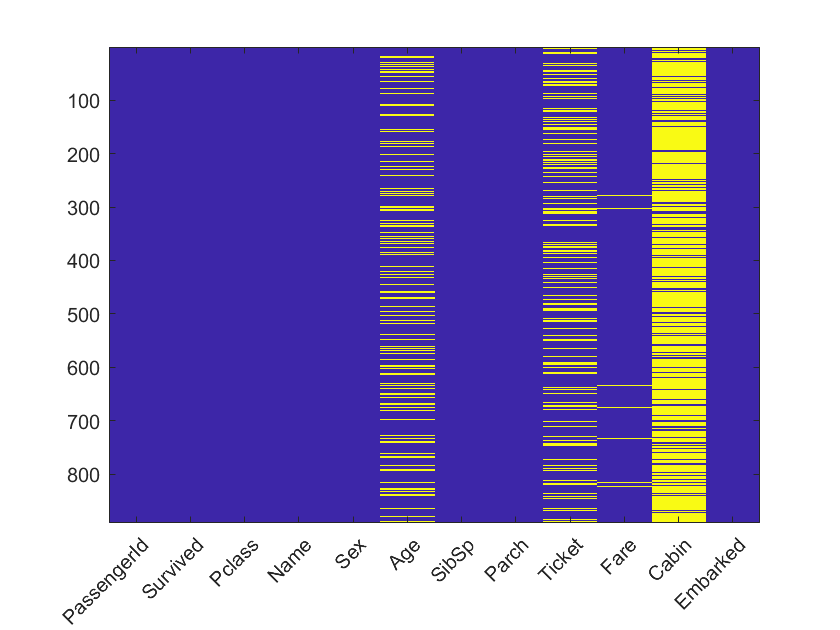

% 提取表头各标签
vars = Train.Properties.VariableNames;
figure
% NaN和空值为强调显示区域
imagesc(ismissing(Train))
% 设定横坐标
set(gca,'XTick', 1:12,'XTickLabel',vars);
% 旋转X标签
xtickangle(45);

## 处理Age特征值数据

% 使用平均值代替NaN

% 忽略NAN的平均值
avgAge = mean(Train.Age ,'omitnan');
Train.Age(isnan(Train.Age)) = avgAge; 
Test.Age(isnan(Test.Age)) = avgAge;

## 处理Fare特征值数据

% 根据船票等级的分别求取其平均值来代替相应的NaN

fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1      1          216         86.149  
    2      2          184         21.359  
    3      3          491         13.788  



for i = 1:height(fare) % height：表行数
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

## 处理Cabin特征值数据

% 将舱室编号转为舱室的个数

% 对多船舱的特殊情况进行预处理：
% cellfun分别对元胞内所有内容应用函数@strsplit：拆分
% ('UniformOutput',false)：要以元胞数组的形式返回数据
train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false); 
% train_cabins全都是元胞数据，其中多仓位数据变为嵌套的3x1cell数组

% **********************************注意：在Train表格内加入新的第13列nCabin:乘客含有的船舱数量***************************************
% 单舱室长度为1，3舱室为3
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins); 

% 以上预处理产生的错误1：因空格的拆分判定，会导致如'F G63'被当作是两个舱室
% 修改原理：只有船舱等级1的人才可能会有多舱室
% 把原来不是一等船舱的，却被误判为有多舱室的修改为1个舱室
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;

% 以上预处理产生的错误2：空舱室被标记为1。因此需要将空舱室标记为0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

## 处理Embarked特征值数据

% 将登船地点的数据转为ASCII数字形式

% 登船地点的存活率（排除空白的统计情况）889-891
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S     {'S'}         644           0.33696   
    C     {'C'}         168           0.55357   
    Q     {'Q'}          77           0.38961   



% 可看出于'C'登船点上船的存活率明显大于其他两个登船点，因此可将Embarked特征值作为训练数据

% 处理缺失的登船地点即空白信息
% 将空值修改为S = Southampton
for i = 1 : 891
    if isempty(Train.Embarked{i})
        Train.Embarked{i}='S';
    end
end
 
for i = 1 : 418
    if isempty(Test.Embarked{i})
        Test.Embarked{i}='S';
    end
end

% 将Embarked的cell数组改为double
% cell2mat：将元胞数组转换为基础数据类型的普通数组
Train.Embarked = double(cell2mat(Train.Embarked));
Test.Embarked = double(cell2mat(Test.Embarked));
% Train.Embarked内的数据转换为ASCII：S-83，Q-81，C-67

## 处理Sex特征值数据

% 将性别数据转为（0-female,1-male）

for i = 1 : 891
    % strcmp：比较字符串，如果二者相同，则返回 1 (true)，否则返回 0 (false)
    if strcmp(Train.Sex{i} ,'male')
        % 将男性设置为 1
        Train.Sex{i}=1;
    else
        Train.Sex{i}=0;
    end
end

for i = 1 : 418
    if strcmp(Test.Sex{i} ,'male')
        Test.Sex{i}=1;
    else
        Test.Sex{i}=0;
    end
end

% 将Sex的cell数组类型改为double
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

# 特征量的选取：Sex, Pclass, Embarked

% 将'Name','Ticket','Age','SibSp','Parch','Ticket','Fare','Cabin','nCabins'特征数据数据剔除Train表
Train(:,{'Name','Ticket','Age','SibSp','Parch','Fare','Cabin','nCabins'}) = [];
Test(:,{'Name','Ticket','Age','SibSp','Parch','Fare','Cabin','nCabins'}) = [];

# Naive Bayes

## 生成训练集的概率矩阵A

% 将Train的Table表转为data的double表
data = Train.Variables;

% 标准化

% 统计训练集样本数
M = size(data,1);
% 存活率,
survival_rate = (sum(data(:,2)==1)+1)/(M+2);
% 死亡率
death_rate = (sum(data(:,2)==0)+1)/(M+2);
% 取训练数据记为x，前几行为特征量数据，最后一行为标签(survival / death)
x = [data(:,3:size(data,2)),data(:,2)]';

% A(i,j)表示第i行的特征量的第j个可能取值对k=(幸存-2,遇难-1)的条件概率矩阵
% 省略初始化A
% A = zeros(size(x,1)-1,size(x,2),2);
for k = 1 : 2
    for i = 1 : size(x,1)-1
        % 统计（i,j,k）的个数 ，再除以k情况下人数 ，即为P
        % B表示在某个k=(幸存-2,遇难-1)的情况下的第i行特征数据
        B = x(i,x(size(x,1),:)==k-1);
        % S为第i行的特征量的所有可能取值集合
        S = unique(x(i,:));
        for j = 1 : size(S,2)
            A(i,j,k) = (sum(B == S(j))+1)/(size(B,2)+size(S,2));
        end
    end
end

## 生成测试集的预测表

% 处理测试集数据Test
data_test = Test.Variables;
% 取训练数据记为x，全为特征量数据
y = data_test(:,2:size(data_test,2))';

% for i = 1 : size(y,2)
%     for j = 1 : size(x,2)
%         if data(j,3) == y(1,i) && data(j,4) == y(2,i)
%             % D(i)为测试集数据y(:,i)对应到训练集数据x的位置
%             D(i) = data(j,1);
%             break;
%         end
%     end
% end

% 获取训练集的所有特征值（不重复升序排列），以便确定A元素的坐标
SS1 = unique(x(1,:));
SS2 = unique(x(2,:));
SS3 = unique(x(3,:));

for i = 1 : size(y,2)
    % m,n,q,p为对应A元素前两维位置
    m = find(SS1 == y(1,i));
    n = find(SS2 == y(2,i));
    o = find(SS3 == y(3,i));
    p1 = death_rate*A(1,m,1)*A(2,n,1)*A(3,o,1);
    p2 = death_rate*A(1,m,2)*A(2,n,2)*A(3,o,2);
    % 比较p1和p2，取最大概率情形，输出到C
    if p1 > p2
        C(i) = 0;
    else
        C(i) = 1;
    end
end

% 生成提交表
D = [(892:1309);C]';
T = array2table(D,'VariableNames',{'PassengerId','Survived'});
writetable(T,'submission.csv')
type submission.csv

PassengerId,Survived
892,0
893,1
894,0
895,0
896,1
897,0
898,1
899,0
900,1
901,0
902,0
903,0
904,1
905,0
906,1
907,1
908,0
909,0
910,1
911,1
912,1
913,0
914,1
915,1
916,1
917,0
918,1
919,0
920,0
921,0
922,0
923,0
924,1
925,1
926,1
927,0
928,1
929,1
930,0
931,0
932,0
933,0
934,0
935,1
936,1
937,0
938,1
939,0
940,1
941,1
942,0
943,1
944,1
945,1
946,1
947,0
948,0
949,0
950,0
951,1
952,0
953,0
954,0
955,1
956,1
957,1
958,1
959,0
960,1
961,1
962,1
963,0
964,1
965,1
966,1
967,1
968,0
969,1
970,0
971,1
972,0
973,0
974,0
975,0
976,0
977,0
978,1
979,1
980,1
981,0
982,1
983,0
984,1
985,0
986,1
987,0
988,1
989,0
990,1
991,0
992,1
993,0
994,0
995,0
996,1
997,0
998,0
999,0
1000,0
1001,0
1002,1
1003,1
1004,1
1005,1
1006,1
1007,0
1008,0
1009,1
1010,1
1011,1
1012,1
1013,0
1014,1
1015,0
1016,0
1017,1
1018,0
1019,1
1020,0
1021,0
1022,0
1023,1
1024,1
1025,0
1026,0
1027,0
1028,0
1029,0
1030,1
1031,0
1032,1
1033,1
1034,1
1035,0
1036,0
1037,0
1038,0
1039,0
1040,0
1041,0
1042,1
1043,0
1044,0
1045,1
1046,0
10